# Problema 1.

**Dos fibras monomodo, de longitudes iguales, por separado ensanchan un pulso gaussiano (sin dispersion) por factores de F1 y F2, F < F2.**

**En cascada las fibras juntas ensanchan el mismo pulso por mas de F2. El factor de ensanchamiento de las dos fibras en cascada debe ser:**

La ecuacion 4.101 del libro de Fundamentos de Comunicaciones Opticas (FCO) nos dice que el factor de ensanchamiento para el caso sin dispersion es


$$\frac{T_z }{T}\;=\sqrt{1+{\left(\frac{\beta_2 z}{T^2 }\right)}^2 }$$


Lo que quiere decir que los factores de ensachamiento de cada fibra por separado, F1 y F2, vienen dados por 

${F_1 }^2 =1+{\left(\frac{\beta_{21} z}{T^2 }\right)}^2$ y ${F_2 }^2 \;=1+{\left(\frac{\beta_{22} z}{T^2 }\right)}^2$

Como F3 > F2 y F2 > F1, podemos asumir dispersion con mismo signo porque el pulso se sigue ensanchando por lo que se **suman **ambos efectos.

En este sentido, el factor de ensanchamiento de las fibras en cascada sera:


$${F_3 }^2 \;=1+{\left(\frac{\beta_{21} z}{T^2 }+\frac{\beta_{22} z}{T^2 }\right)}^2 \longrightarrow \sqrt{{F_3 }^2 -1}=\sqrt{{F_1 }^2 -1}+\sqrt{{F_2 }^2 -1}$$



$$F_3 =\sqrt{{\left(\sqrt{{F_1 }^2 -1}+\sqrt{{F_2 }^2 -1}\right)}^2 +1}$$


## Un ejemplo numerico:

F1 = sqrt(2) % Factor primera fibra

F1 = 1.4142

F2 = sqrt(8) % // Factor segunda fibra

F2 = 2.8284

F3 = sqrt( (sqrt(F1^2 - 1) + sqrt(F2^2 - 1))^2 + 1) % Factor calculado de ensanchamiento de fibras en cascada

F3 = 3.7804

Para un pulso gaussianiano en z = 0, 


$$P\left(z=0,t\right)=\exp \left(-\frac{t^2 }{T^2 }\right)$$


donde $T=\sqrt{2}\sigma$ donde $\sigma$ es la desviación estándar, a veces llamada [media cuadrática o valor cuadrático medio](https://es.wikipedia.org/wiki/Media_cuadr%C3%A1tica) y controla el ancho de la campana (mientras mas grande sea, mas ancha sera la campana).

delta = 1; % Ancho de la fuente en z=0
t = -15:0.1:15

t =   -15.0000  -14.9000  -14.8000  -14.7000  -14.6000  -14.5000  -14.4000  -14.3000  -14.2000  -14.1000  -14.0000  -13.9000  -13.8000  -13.7000  -13.6000  -13.5000  -13.4000  -13.3000  -13.2000  -13.1000  -13.0000  -12.9000  -12.8000  -12.7000  -12.6000  -12.5000  -12.4000  -12.3000  -12.2000  -12.1000  -12.0000  -11.9000  -11.8000  -11.7000  -11.6000  -11.5000  -11.4000  -11.3000  -11.2000  -11.1000  -11.0000  -10.9000  -10.8000  -10.7000  -10.6000  -10.5000  -10.4000  -10.3000  -10.2000  -10.1000


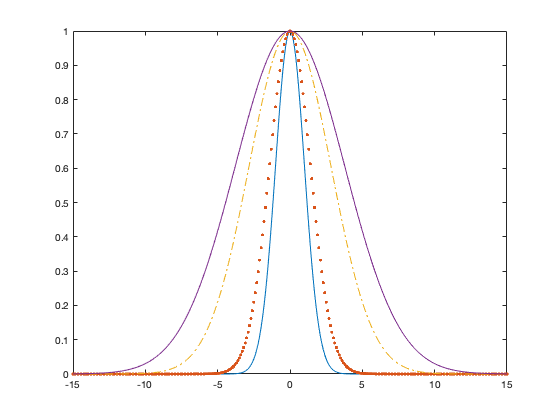

p0 = exp(-t.^2 / (2*(delta)^2));
p1 = exp(-t.^2 / (2*(F1*delta)^2));
p2 = exp(-t.^2 / (2*(F2*delta)^2));
p3 = exp(-t.^2 / (2*(F3*delta)^2));
plot(t, p0, '', t, p1, '.', t, p2, '-.', t, p3, '')

## Problema 1.2 ( Un problema similar con condiciones diferentes) [FALTA VERIFICAR]

**Dos fibras monomodo, de longitudes iguales, por separado ensanchan un pulso gaussiano (sin dispersión) por factores en tiempo de F1 y F2 respectivamente. **

**En cascada las fibras juntas ensanchan el mismo pulso por menos de F2.**

**El factor de ensanchamiento de las dos fibras en cascada debe ser:**

F1 = 2; F2 = sqrt(10); % Datos del problema

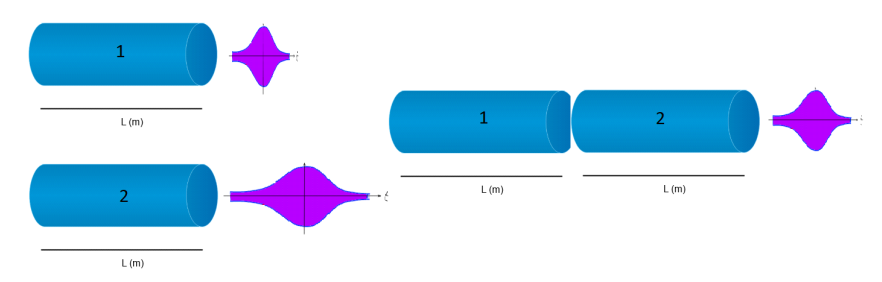

Para estos valores concretos de F1 y F2, el resultado del problema anterior da un Factor total de ensanchamiento de

F3 = sqrt( (sqrt(F1^2 - 1) + sqrt(F2^2 - 1))^2 + 1) % Factor calculado de ensanchamiento de fibras en cascada

F3 = 4.8366

Pero el problema dice que F3 < F2 por lo que se dejan de sumar ambos efectos y se **restan**

F3 = sqrt( (sqrt(F1^2 - 1) - sqrt(F2^2 - 1))^2 + 1) % Factor calculado de ensanchamiento de fibras en cascada

F3 = 1.6148

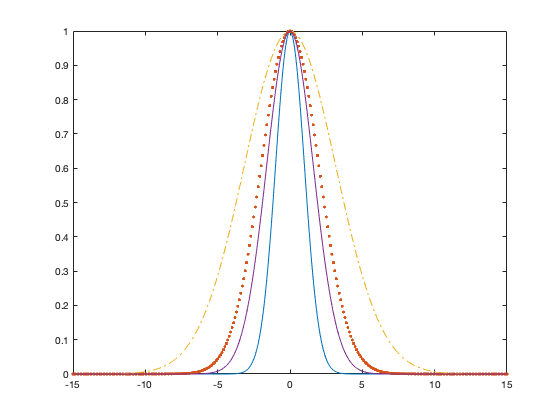


p0 = exp(-t.^2 / (2*(delta)^2));
p1 = exp(-t.^2 / (2*(F1*delta)^2));
p2 = exp(-t.^2 / (2*(F2*delta)^2));
p3 = exp(-t.^2 / (2*(F3*delta)^2));
plot(t, p0, '', t, p1, '.', t, p2, '-.', t, p3, '')